# Practical 9

## Question Form

Phthalic Anhydride (PA) is industrially produced by the oxidation of the o-xylene on $V_2 O_5 -{\textrm{TiO}}_2$  catalyst. The o-xylene diluted in air is fed to a multi tubular fixed bed reactor cooled by the circulation of  a molten salts. Details of the configuration, catalysts, and operating conditions are given below. The  reaction network is given by the following three reactions:


$$\begin{array}{l}
C_6 H_4 {\left({\textrm{CH}}_3 \right)}_2 +3O_2 \to C_6 H_4 {\left(\textrm{CO}\right)}_2 O+3H_2 O\;\;\left(1\right)\;\;\;\;\;\;\;\;\Delta H=-1285409\;\frac{\textrm{kJ}}{\textrm{kmol}}\\
C_6 H_4 {\left({\textrm{CH}}_3 \right)}_2 +10\ldotp 5O_2 \to 8{\textrm{CO}}_2 +5H_2 O\;\;\;\;\;\left(2\right)\;\;\;\;\;\;\;\;\;\;\;\;\Delta H=-4564000\;\frac{\textrm{kJ}}{\textrm{kmol}}\\
C_6 H_4 {\left(\textrm{CO}\right)}_2 O++7\ldotp 5O_2 \to 8{\textrm{CO}}_2 +2H_2 O\;\;\;\;\left(3\right)\;\;\;\;\;\;\;\;\;\;\Delta H=-327859\;\frac{\textrm{kJ}}{\textrm{kmol}}
\end{array}$$


The system can be considered a mixture of ideal gases. Adopting a 1D+1D pseudo homogeneous model  with the heat transfer computed through the Dixon-Specchia correlation, assess: 

- the number of tubes needed considering the constraints reported in the data. 

- the thermal profile along the tube. 

- the conversion of C6H4(CH3)2 and the selectivity of C6H4(CO)2O along the tube. 

## Theory

### 1D + 1D Heterogeneous Model

first 1D represents the reactor and the second 1D represents the pellet. The diffusion coefficient for gas phase in a sphere is expressed as follows:


$$\begin{array}{l}
D_i =\frac{D_{\textrm{eff}} }{\textrm{RT}}\;\mu \omega_i \;\frac{{\textrm{dP}}_i }{\textrm{dr}}\\
P_i =P\ldotp x_i =P\ldotp \frac{\omega_i }{{\textrm{MW}}_i }\ldotp {\textrm{MW}}_{\textrm{mix}} 
\end{array}$$


The effective diffusion described as below:


$$D_{\textrm{eff}} =D_i \;\frac{\varepsilon }{\tau }$$


Which $\varepsilon \;,\tau$ represents the porosity and tortuosity ($\varepsilon /\tau$ model) 


$$\frac{1}{D_{\textrm{eff}} }=\frac{1}{D_{\textrm{eff},c} }+\frac{1}{D_{\textrm{eff},\textrm{KN}} }$$


Therefore, the diffusion coefficient is expressed as follows:


$$\begin{array}{l}
D_i =\frac{D_{\textrm{eff}} }{\textrm{RT}}\;{\textrm{MW}}_i \;\frac{d}{\textrm{dr}}\left(\frac{P\omega_i }{{\textrm{MW}}_i }\;{\textrm{MW}}_{\textrm{mix}} \right)=\frac{D_{\textrm{eff}} }{\textrm{RT}}\;\frac{d}{\textrm{dr}}\left(P\omega_i \;{\textrm{MW}}_{\textrm{mix}} \right)\\
,@\;r=0>\frac{d}{\textrm{dr}}\left(\omega_i {\textrm{MW}}_{\textrm{mix}} \right)=0
\end{array}$$


We need to B.C to solve ODE system; 1 in the center of pellet, and 1 in the surface of the pellet. 


$$@\;r=0\Rightarrow \frac{\textrm{dT}}{\textrm{dr}}=0$$



$$\begin{array}{l}
-\frac{1}{r^2 }\frac{d}{\mathrm{dr}}\left(r^2 D_i \right)+\sum_{j=1}^{\mathrm{NR}} \nu_{i,j} r_j \rho_{\mathrm{cat}} {\mathrm{MW}}_j =0\\
\Rightarrow \;+\frac{1}{r^2 }\frac{d}{\mathrm{dr}}\left\lbrack r^2 \frac{D_{\mathrm{eff}} }{\mathrm{RT}}{\mathrm{MW}}_i \frac{d}{\mathrm{dr}}\left(\frac{P\omega_i {\mathrm{MW}}_{\mathrm{mix}} }{{\mathrm{MW}}_i }\right)\right\rbrack +\sum_{j=1}^{\mathrm{NR}} \nu_{i,j} r_j \rho_{\mathrm{cat}} {\mathrm{MW}}_j =0\\
\Rightarrow \;\frac{1}{r^2 }\frac{P}{R}\left\lbrack 2r\ldotp \frac{D_{\mathrm{eff}} }{T}\frac{d}{\mathrm{dr}}\left(\omega_i {\mathrm{MW}}_{\mathrm{mix}} \right)+r^2 \frac{d}{\mathrm{dr}}\left(\frac{D_{\mathrm{eff}} }{T}\frac{d}{\mathrm{dr}}\left(\omega_i {\mathrm{MW}}_{\mathrm{mix}} \right)\right)\right\rbrack +\sum_{j=1}^{\mathrm{NR}} \nu_{i,j} r_j \rho_{\mathrm{cat}} {\mathrm{MW}}_j =0\\
\frac{d}{\mathrm{dr}}\left(\omega_i {\mathrm{MW}}_{\mathrm{mix}} \right)=Y_{P-r} \;\\
\frac{1}{r^2 }\;\frac{P}{R}\left\lbrack 2r\;\frac{D_{\mathrm{eff}} }{T}\frac{d}{\mathrm{dr}}\left(\omega_i {\mathrm{MW}}_{\mathrm{mix}} \right)+r^2 \left\lbrack \frac{d}{\mathrm{dr}}\left(\frac{D_{\mathrm{eff}} }{T}\right)\frac{d}{\mathrm{dr}}\left(\omega_i {\mathrm{MW}}_{\mathrm{mix}} \right)+\frac{D_{\mathrm{eff}} }{T}\frac{d^2 }{{\mathrm{dr}}^2 }\left(\omega_i {\mathrm{MW}}_{\mathrm{mix}} \right)\right\rbrack \right\rbrack +\sum_{j=1}^{\mathrm{NR}} \nu_{i,j} r_j \rho_{\mathrm{cat}} {\mathrm{MW}}_j =0
\end{array}$$


Hence, the boundary condition for the pellet is written as follows:


$$\begin{array}{l}
\mathrm{@J}=1\;\left(\mathrm{Center}\;\mathrm{of}\;\mathrm{the}\;\mathrm{pellet}\right)\Rightarrow \frac{d}{\mathrm{dr}}\left({\mathrm{MW}}_{\mathrm{mix}} \omega_i \right)=o,\frac{\mathrm{dT}}{\mathrm{dr}}=0\\
@\;2<J<\left(\mathrm{NR}-1\right)\;\left\lbrack \mathrm{Inside}\;\mathrm{the}\;\mathrm{pellet}\right\rbrack \Rightarrow \frac{1}{r^2 }\;\frac{P}{R}\left\lbrack 2r\;\frac{D_{\mathrm{eff}} }{T}\frac{d}{\mathrm{dr}}\left(\omega_i {\mathrm{MW}}_{\mathrm{mix}} \right)+r^2 \left\lbrack \frac{d}{\mathrm{dr}}\left(\frac{D_{\mathrm{eff}} }{T}\right)\frac{d}{\mathrm{dr}}\left(\omega_i {\mathrm{MW}}_{\mathrm{mix}} \right)+\frac{D_{\mathrm{eff}} }{T}\frac{d^2 }{{\mathrm{dr}}^2 }\left(\omega_i {\mathrm{MW}}_{\mathrm{mix}} \right)\right\rbrack \right\rbrack +\sum_{j=1}^{\mathrm{NR}} \nu_{i,j} r_j \rho_{\mathrm{cat}} {\mathrm{MW}}_j =0\\
@\;2<J<\left(\mathrm{NR}-1\right)\;\left\lbrack \mathrm{Inside}\;\mathrm{the}\;\mathrm{pellet}\right\rbrack \Rightarrow \frac{\lambda }{r^2 }\left\lbrack 2r\;\frac{\mathrm{dT}}{\mathrm{dr}}+r^2 d^2 \frac{T}{{\mathrm{dr}}^2 }\right\rbrack -\sum_{j=1}^{\mathrm{NR}} \Delta \tilde{H_{r_j } } r_j \rho_{\mathrm{cat}} =0\\
@\;J=\mathrm{NR}\Rightarrow \omega_i =\bar{\omega_i } \;,T_i =\bar{T_i } 
\end{array}$$


The catalyst Efficiency described as follows:


$$\eta =\frac{\int_0^{V_p } R_i }{V_p \;R_{\mathrm{surface}} }$$


## 1D+1D psuodo homogeneous model

y((NR+1)(NS+1)+1) = NR.NS + NS + NR + 1 + 1


$$\begin{array}{l}
\rho_g \;K_c \;a_V \left(\omega_{i,g} -\omega_{i,s} \right)+\frac{\int_0^{V_p } \sum \nu_{i,j} r_j \rho_{\mathrm{cat}} \;{\mathrm{MW}}_i \;{\mathrm{dV}}_p }{V_p }=0\\
a_V =\frac{6}{d_p }
\end{array}$$


## Initial Data

close all, clear, clc
global NR NS NEQ mw N_reactions deltaH Stoichiometry diffusivity0 epsi tau pore_diameter ...
    delta_r CatalystDensity pressure r_vector lambda_cat yIN
% i => index for the species
% j => index for the radial points
%% Parameters and Initialization
%Reaction:
Stoichiometry=[0 -3 -1 1 +3 0
               0 -10.5 -1 0 5 8
               0 -7.5 0 -1 2 8];

deltaH=[-1285409 -4564000 -3278591]; %kJ/kmol
diffusivity0=[8.31e-5 7.02e-5 2.58e-5 2.22e-5 8.98e-5 2.02e-5]; %m2/s

%-species:
mw=[28 32 106.16 148.12 18 44]; %kg/kmol
NS = 6; % number of species
N_reactions = 3; % number of reactions
NEQ = NS+1; % number of equations

%-Reactor:
ParticleDiameter=0.005; %m
ParticleRadius = ParticleDiameter/2;
CatalystDensity=2100; %kg/m3
lambda_cat=1.5; %W/m/K

Temperature=335+273.15; %K
oXylToAirRatio=0.013;
n_in=[0.79 0.21 oXylToAirRatio 0 0 0]; %moles
ntot_in = sum(n_in);
for i = 1:NS
    MolarFractionIN(i) = n_in(i)/ntot_in;
end
pressure=1.3*1e5; %Pa

basis_calc=1; %kmol
for i=1:NS
    mass(i)=MolarFractionIN(i)*basis_calc*mw(i); %kg
end
mtot = sum(mass);

for i = 1:NS
    MassFractionIN(i) = mass(i)/mtot;
end

## Pellet Discretization

NR=80; % Number of radial points
initial_point = 0e-3;
r_vector=linspace(initial_point,ParticleRadius,NR);
delta_r = r_vector(2)-r_vector(1);
epsi=0.3;
tau=5;
pore_diameter=1e-8; %m

## Solving The equations

%initial guess for the fsolve
yIN = [MassFractionIN Temperature];
y_trial = zeros(1,NR*NEQ); 

for i = 1:NEQ
    for j = 1:NR
        y_trial((j-1)*NEQ+i) = yIN(i);
    end
end
y = fsolve('diffusion_reaction',y_trial); 


Equation solved, solver stalled.

fsolve stopped because the relative size of the current step is less than the
value of the step size tolerance squared and the vector of function values
is near zero as measured by the value of the function tolerance.

<stopping criteria details>


## Post Processing

solution = zeros(NR,NEQ);
for i = 1:NEQ
    for j = 1:NR
        solution(j,i) = y((j-1)*NEQ+i); 
    end
end
mol=zeros(NR,NS);
basis_calc = 1; % kgtot
for j=1:NR
    for i=1:NS
        mol(j,i)=solution(j,i)/mw(i)*basis_calc; %mol
    end
    MolarFractionSolid(j,:)=mol(j,:)./sum(mol(j,:));
end

%conversion o-xylene:
for j=1:NR
    conv_o_xyl(j)=(mol(NR,3)-mol(j,3))/(mol(NR,3));
end

%selectivity to PA:
for j=1:NR
    sel_PA(j)=mol(j,4)/(mol(NR,3)-mol(j,3)+1e-12);
end

%yield:
for j=1:NR
    yield(j)=conv_o_xyl(j)*sel_PA(j);
end

% evaluation of the catalyst efficiency
TemperatureSolid = solution(:,end);
Pressure_bar = pressure/1e5; % bar
NetRateProduction=zeros(NR,NS);
RateH=zeros(NR,1);

for j=1:NR
    ReactionK(1)=exp(19.837-13636/TemperatureSolid(j));
    ReactionK(2)=exp(18.970-14394/TemperatureSolid(j));
    ReactionK(3)=exp(20.860-15803/TemperatureSolid(j));
    ReactionRate(1)=ReactionK(1)*Pressure_bar*MolarFractionSolid(j,3)*...
        Pressure_bar*MolarFractionSolid(j,2);
    ReactionRate(2)=ReactionK(2)*Pressure_bar*MolarFractionSolid(j,3)*...
        Pressure_bar*MolarFractionSolid(j,2);
    ReactionRate(3)=ReactionK(3)*Pressure_bar*MolarFractionSolid(j,4)*...
        Pressure_bar*MolarFractionSolid(j,2); %kmol/kg_cat_/h

    for k=1:N_reactions                    
        for i=1:NS
            NetRateProduction(j,i)=NetRateProduction(j,i)+...
                Stoichiometry(k,i)*ReactionRate(k);
        end
        RateH(j)=RateH(j)+deltaH(k)*ReactionRate(k); %kJ/kg_cat/h
    end
end

r_vector = (r_vector-initial_point)/(ParticleRadius-initial_point);

V=4/3*pi*r_vector.^3;
Ri=trapz(V,NetRateProduction(:,3)*CatalystDensity*mw(3)/3600)/(4/3*pi*(r_vector(end)^3-r_vector(1)^3));
Rsurface = NetRateProduction(end,3)*CatalystDensity*mw(3)/3600;

catalyst_efficiency = Ri/Rsurface*100;
disp("eta: "+catalyst_efficiency)

eta: 72.2526


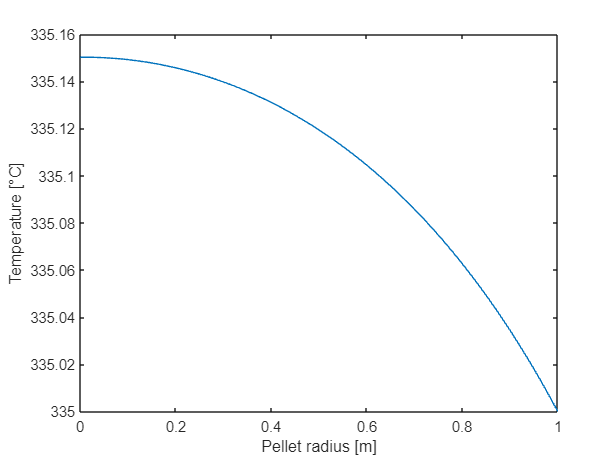


Ri_actual = zeros(NR,1);
for j = 1:NR
    Ri_actual(j) = NetRateProduction(j,3)*CatalystDensity*mw(3)/3600;
end

effectiveness_factor = Ri_actual./Rsurface;

figure(1)
plot(r_vector,solution(:,7)-273.15)
hold on
xlabel('Pellet radius [m]')
ylabel('Temperature [°C]')

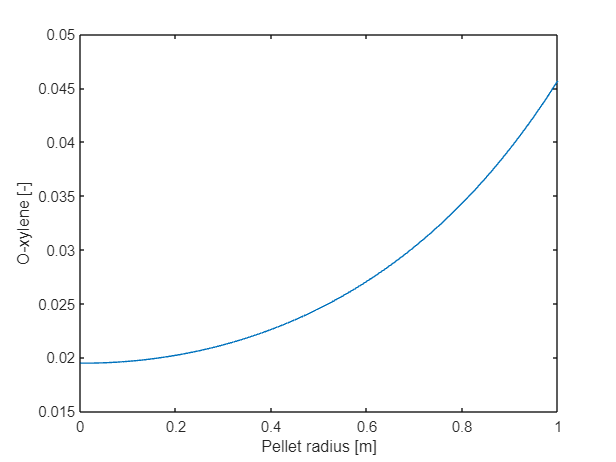

figure(2)
plot(r_vector,solution(:,3))
hold on
xlabel('Pellet radius [m]')
ylabel('O-xylene [-]')

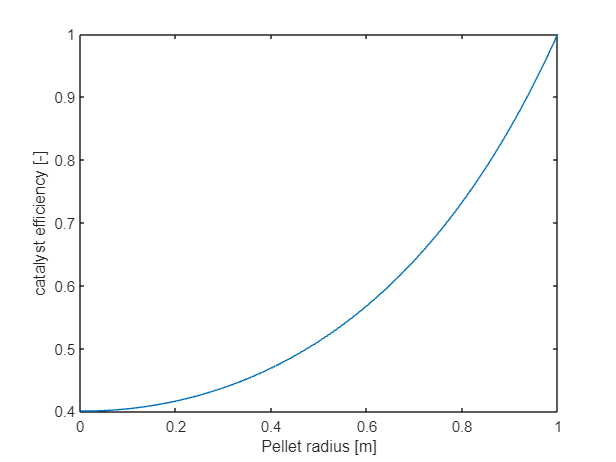

figure(3)
plot(r_vector,effectiveness_factor)
hold on
xlabel('Pellet radius [m]')
ylabel('catalyst efficiency [-]')